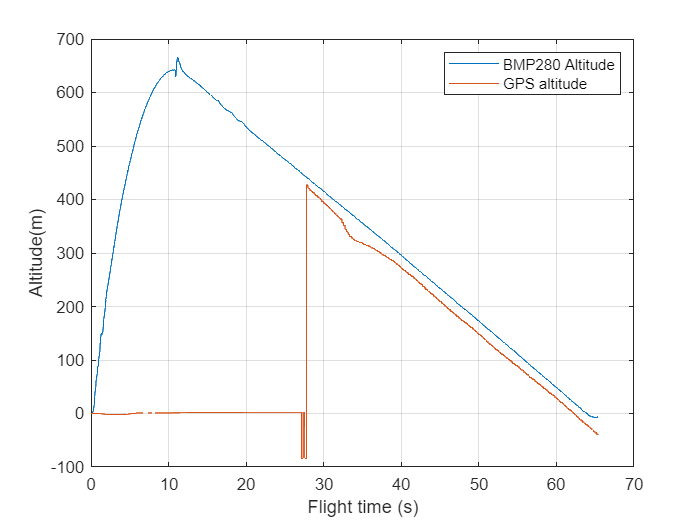

data = csvread("theLAUNCH.csv");
launchStartIndex = 53585;
launchEndIndex = 60130;
data = data(launchStartIndex:launchEndIndex, :);

flightTime = (launchEndIndex-launchStartIndex) / 100; % we are dataLogging every 10ms, so 100Hz
bmpAlt = data(:, 20);
bmpAlt = bmpAlt - bmpAlt(1);
bmpPressure = data(:, 19);

timestamps = data(:, 2);
time = (timestamps - timestamps(1)) / 1000; % Timestamps are in ms
gpsLat = data(:, 21);
gpsLon = data(:, 22);
gpsAlt = data(:, 23);
gpsAlt = gpsAlt - gpsAlt(1);
DRZ = data(:,29);
BNOaccx = data(:,9);
ADXLaccx = data(:,15);

plot(time, bmpAlt)
hold on
plot(time, gpsAlt)
legend("BMP280 Altitude", "GPS altitude")
grid on
xlabel("Flight time (s)");
ylabel("Altitude(m)")
hold off

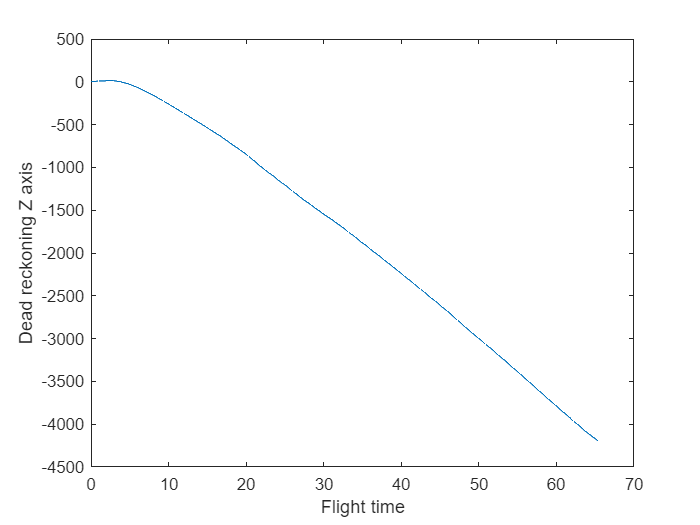


plot(time, DRZ)
ylabel("Dead reckoning Z axis")
xlabel("Flight time")

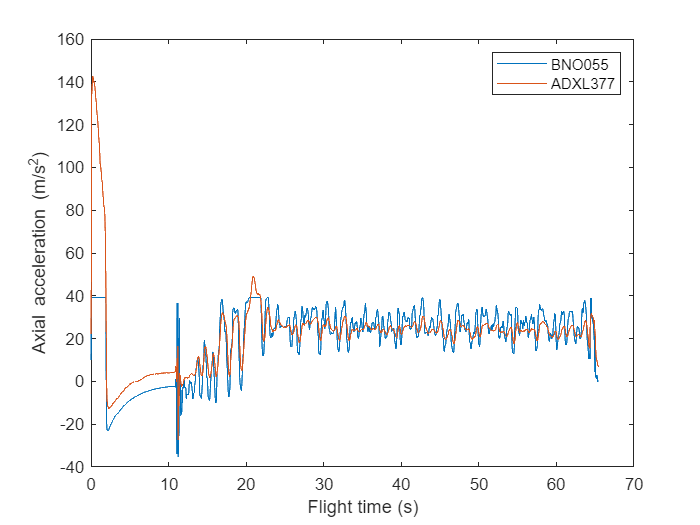


% seaLevelHpa = 1024;
% altitude = 44330 * (1.0 - ((bmpPressure/100) / seaLevelHpa).^0.1903);
% altitude = altitude - altitude(1)
% plot(altitude)
% hold on
% plot(bmpAlt)
% grid on
% ylabel("Altitude")
% xlabel("Flight time (s)")
% legend("BMP1024hpa", "BMP1010hpa")
% hold off

%plot(gpsLon)
%plot(gpsLat)
plot(time, BNOaccx)
hold on
plot(time, ADXLaccx)
legend("BNO055", "ADXL377")
xlabel("Flight time (s)");
ylabel("Axial acceleration (m/s^2)")
hold off


% hold off
% 
% ADXLvelx = cumtrapz(time(1:3000), ADXLaccx(1:3000));
% plot(time(1:3000), ADXLvelx)
% ylabel("Velocity")
% ADXLposx = cumtrapz(time(1:3000), ADXLvelx(1:3000));
% plot(time(1:3000), ADXLposx)
% ylabel("DRZ")